### Przykład 1:

Optymalizacja z ograniczeniami, Matlab Optimization Toolbox. Zadanie sprowadza się do wykorzystania parametryzacji funkcji "fmincon", niewykorzystane argumenty deklaruje się jako „[]”, np.:


clear

fun = @(x)(1-x(1)).^2+(5*x(2)-x(1).^2).^2 % funkcja celu

fun = function_handle with value:
    @(x)(1-x(1)).^2+(5*x(2)-x(1).^2).^2



x0 = [-3,4]; %Warunki początkowe
% przy ograniczeniach liniowych:  x1-x2+4<=0  i  2x1+x2=-4
A = [1,-1];
b = -4;
Aeq = [2,1];
beq = -4;
ub=[10, 1.4];

% przy ograniczeniach nieliniowych "ellipseparabola(x)"
%  (x(1)^2)/9 + (x(2)^2)/4 <= 1
%   x(2) >= x(1)^2 - 1

options = optimset('Display','iter','PlotFcns',@optimplotfval)

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: @optimplotfval
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeSca

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.430250e+01    1.590e+00    1.581e+01
    1       6    2.377205e+01    8.059e-01    6.618e+01    9.902e-01
    2       9    1.693697e+01    3.161e-01    5.899e+00    4.521e-01
    3      12    1.517163e+01    2.031e-01    3.713e+00    2.695e-01
    4      15    1.398215e+01    5.652e-02    6.386e-01    1.583e-01
    5      18    1.373223e+01    0.000e+00    2.327e-01    8.338e-02
    6      21    1.365309e+01    0.000e+00    3.775e-02    4.621e-02
    7      24    1.364554e+01    0.000e+00    9.102e-03    5.127e-03
    8      27    1.364223e+01    0.000e+00    2.424e-04    2.302e-03
    9      30    1.364198e+01    8.882e-16    2.623e-06    1.787e-04


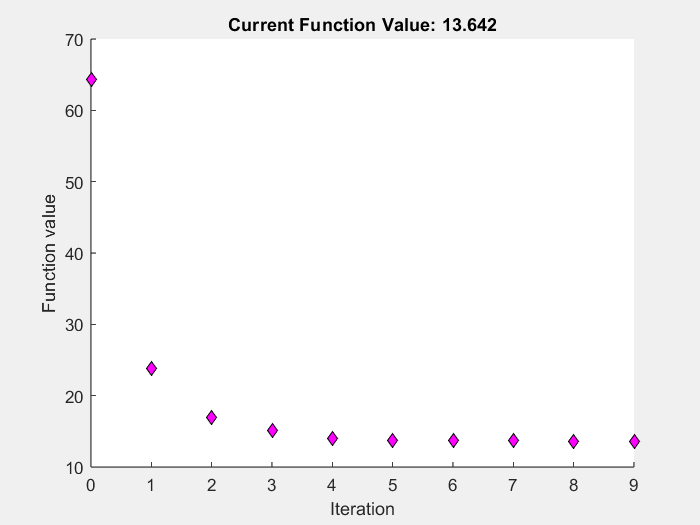


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    -2.6667    1.3333



% Rozwiązanie:
nonlcon = @ellipseparabola; % ograniczenia nieliniowe
x = fmincon(fun,x0,A,b,Aeq,beq,[],ub,[],options) % bez ograniczeń nieliniowych

f=fun(x)

f = 13.6420

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.430250e+01    7.590e+00    7.253e+00
    1       6    6.296891e+01    7.374e+00    7.756e+00    5.561e-02
    2       9    6.238724e+01    7.356e+00    8.350e+00    6.184e-03
    3      12    6.138964e+01    7.327e+00    9.360e+00    1.100e-02
    4      15    6.138467e+01    7.326e+00    9.365e+00    5.464e-05
    5      18    8.471206e+00    1.904e+00    4.149e-02    1.100e+00
    6      21    7.985012e+00    1.580e+00    1.580e+00    2.375e-01
    7      24    1.139788e+01    1.441e+00    1.076e+00    3.663e-01
    8      27    1.339286e+01    1.549e+00    1.110e+00    1.050e-01
    9      30    1.511062e+01    1.506e+00    1.225e+00    1.298e-01
   10      33    1.637840e+01    1.608e+00    9.423e-01    4.610e-02
   11    

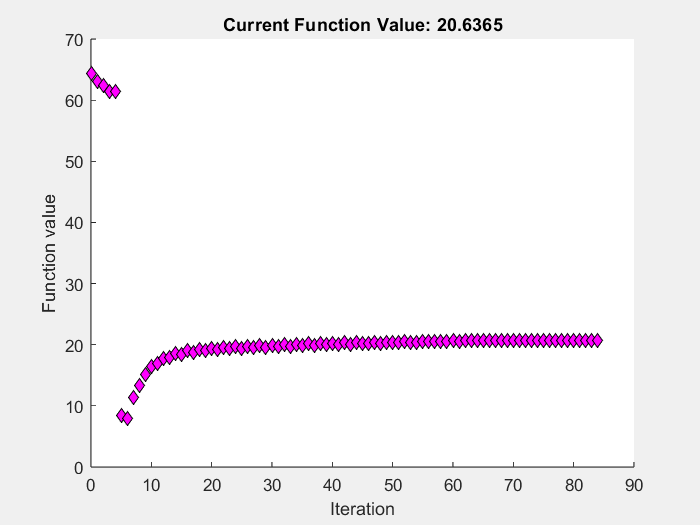


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



x =    -1.8638    1.4000


x = fmincon(fun,x0,A,b,Aeq,beq,[],ub,nonlcon,options) % z ograniczeniami nieliniowymi

f=fun(x)

f = 20.6365

### Przykład 2:

% x = fmincon(fun,x0,A,b,Aeq,beq)
% Przykłady ograniczeń liniowych równościowych i nierównościowych.
fun = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
x0 = [0.5,0];
A = [1,2];
b = 1;
Aeq = [-2/abs(-2),1]
beq = 1;
x = fmincon(fun,x0,A,b,Aeq,beq)
%abs
%{
function [c,ceq] = mycon(x)
c = ... % Compute nonlinear inequalities at x.
ceq = ... % Compute nonlinear equalities at x.
%}
% Przykłady ograniczeń nieliniowych równościowych i nierównościowych.
% https://www.mathworks.com/help/optim/ug/nonlinear-constraints.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_8
% Anonymous Nonlinear Constraint Functions
% https://www.mathworks.com/help/optim/ug/nonlinear-constraints.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_8
c = @(x)[x(1)^2/9 + x(2)^2/4 - 1;
x(1)^2 - x(2) - 1];
ceq = @(x)tanh(x(1)) - x(2);
nonlinfcn = @(x)deal(c(x),ceq(x));
obj = @(x)cosh(x(1))+sinh(x(2));
opts = optimoptions(@fmincon,'Algorithm','sqp');
z = fmincon(obj,[0;0],[],[],[],[],[],[],nonlinfcn,opts)
[cout,ceqout] = nonlinfcn(z)

function [c,ceq] = ellipseparabola(x)  % funkcja ograniczeń nieliniowych
c(1) = (x(1)^2)/9 + (x(2)^2)/4 - 1;
c(2) = x(1)^2 - x(2) - 1;
ceq = [];
end